# Design controllers

clear all
close all
clc

load modello_j1.mat
load modello_j2.mat

max_acc=10; % rad/s^2
vel_max=10; % rad/s
st=1e-3;

s=tf('s');
p1=[modello_continuo_tf_j1/s;
    modello_continuo_tf_j1];


p2=[modello_continuo_tf_j2/s;
    modello_continuo_tf_j2];


Design reference

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=5; %rad/s
w1=max_acc*10; %rad/s
t=(0:st:10*(2*pi)/w0)';
control_action = vel_max*chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
integrated_action = cumtrapz(t,control_action)

integrated_action =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Sommo i due segnali

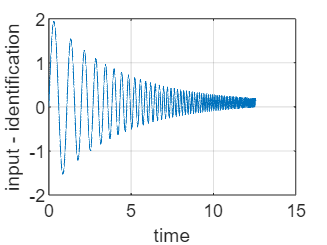

figure
plot(t,integrated_action)
xlabel('time')
ylabel('input - identification')
grid on

cost = @(x) cascade_optimization_cost(x,modello_continuo_tf_j1,600,st,[zeros(1,100) ones(1,5000)]);
[cost, Y] = cost([1 1000 10]);

plot(t,integrated_action,t,Y)
legend("ref","out")
ylim([-2 2])